# Tribell Laplacian program

Computes the eigenvalues and eigenfunctions of the Laplace operator on the *Tribell *quantum graph

## Set up the graph structure and coordinates of the problem

We use the default settings for the `nbell` template, which has three arms. 

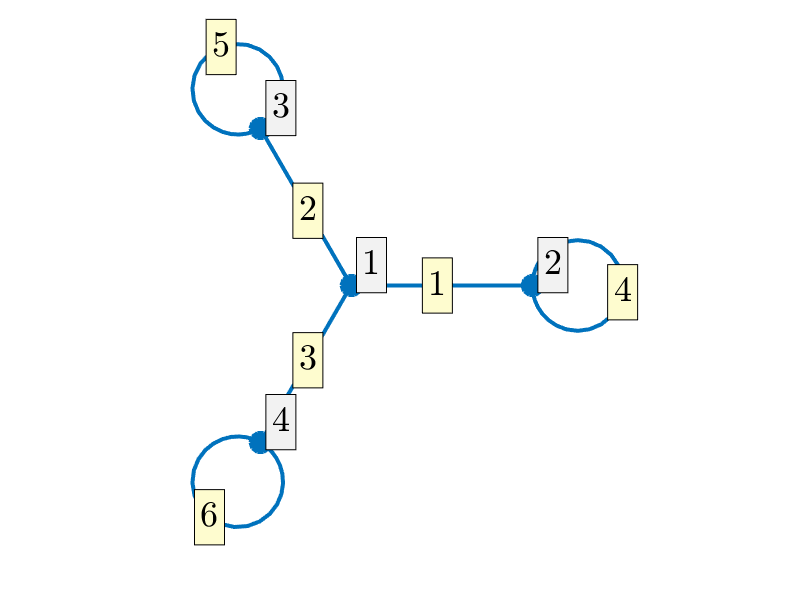

Phi = quantumGraphFromTemplate('multibell','Discretization','Chebyshev','nx',32);
Phi.plot('layout')

## Construct the Laplacian and calculate its eigenvalues and eigenvectors

A little cleanup needed because the null eigenvalue is sometimes is calculated as positive and sometimes as negative and this screws up the sorting.

[V,lambda]=eigs(Phi,24);
[singles,doubles,triples]=separateEigs(lambda);
nToPlot=4;

## Plot the first few multiplicity-one eigenfunctions

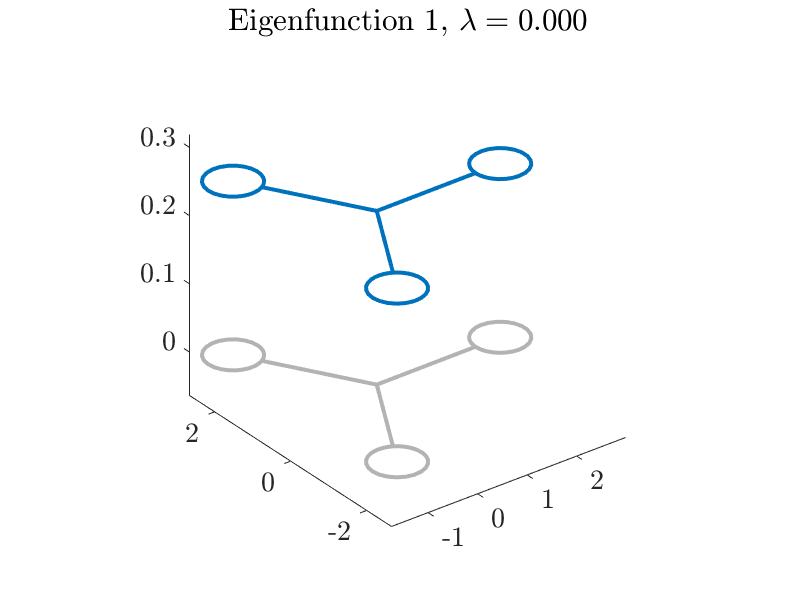

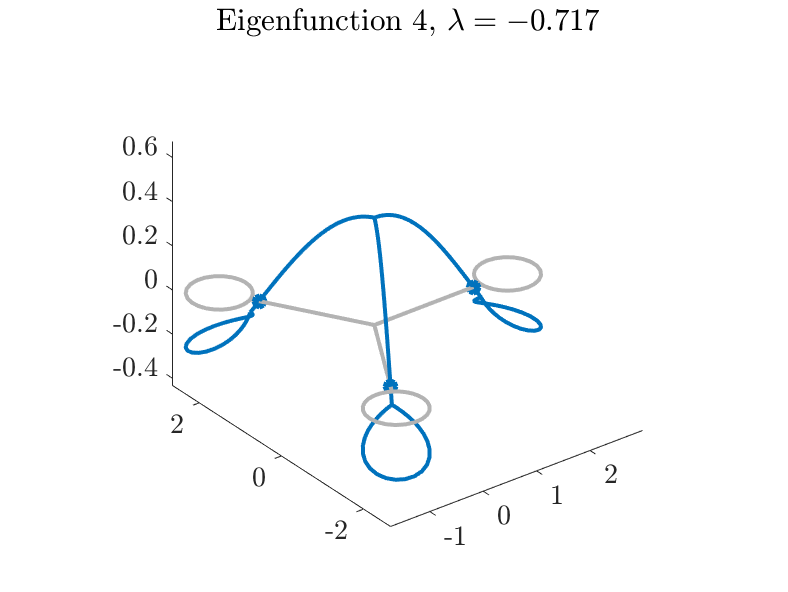

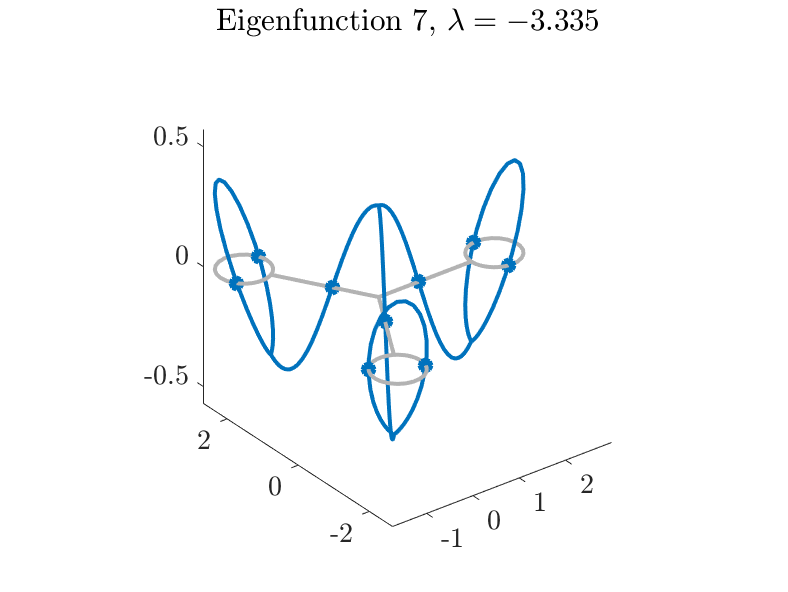

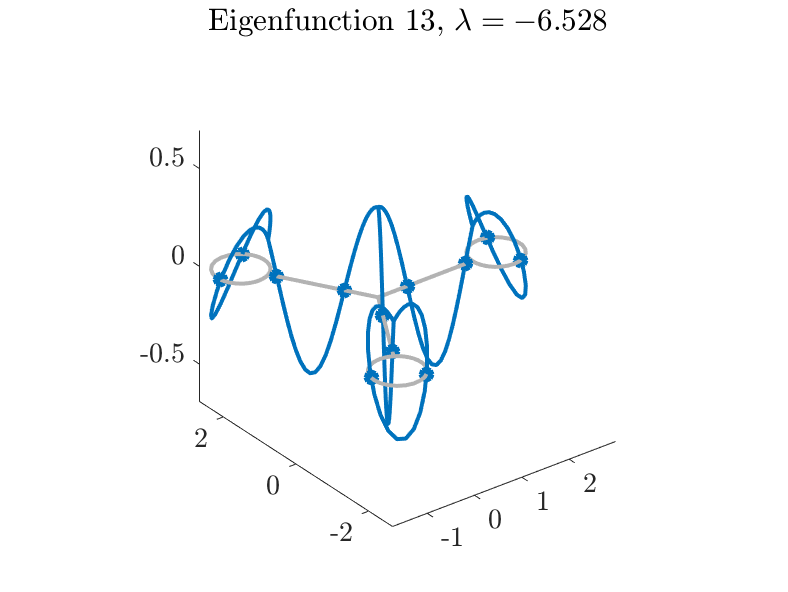

for k=1:min(nToPlot,length(singles))
    figure
    if(V(1,singles(k))<0)
        V(:,singles(k))=-V(:,singles(k));
    end
    Phi.plot(V(:,singles(k)))
    title(sprintf('Eigenfunction %i, $\\lambda = %0.3f$',singles(k), lambda(singles(k))));
end

## Plot the first few multiplicity-two eigenfunctions

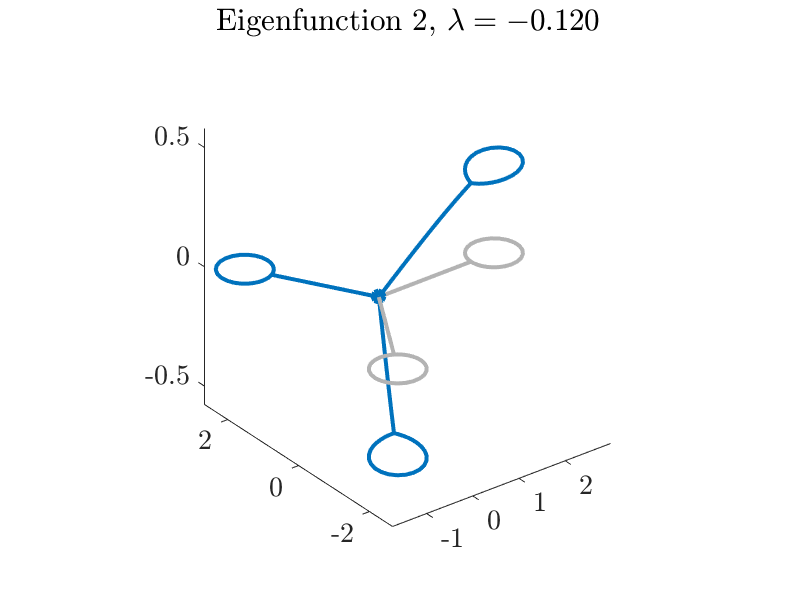

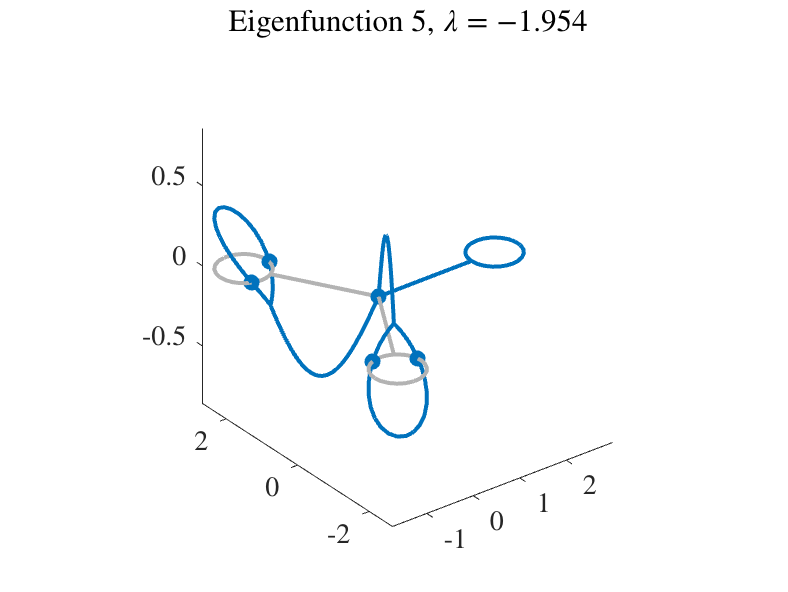

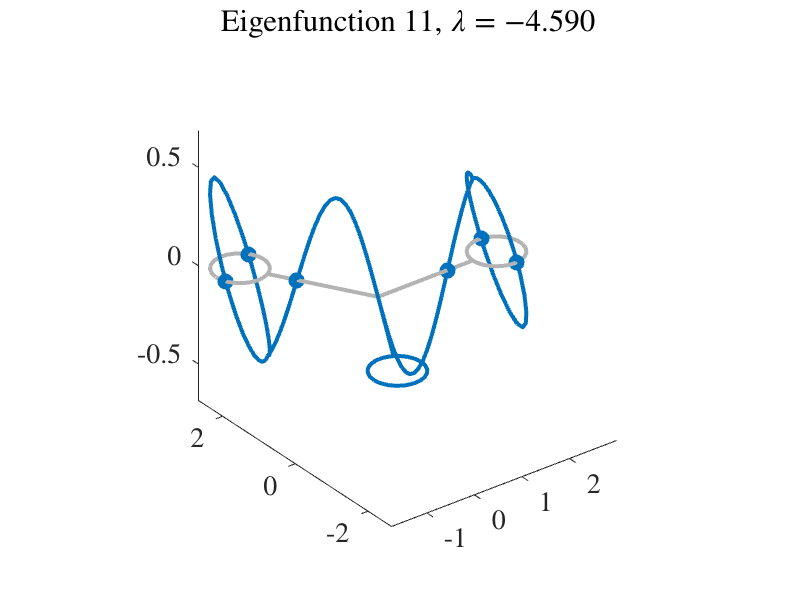

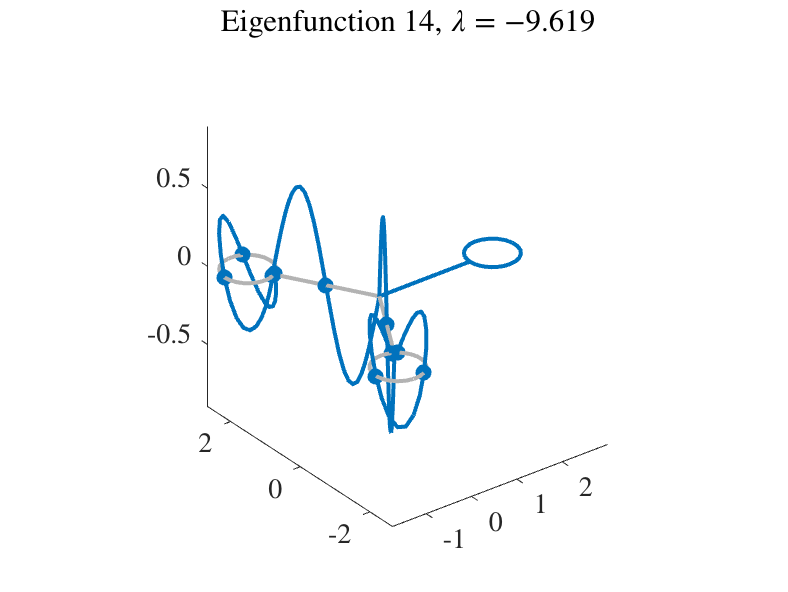

for k=1:min(nToPlot,length(doubles))
    figure
    v=tribellResolveDoubles(V,doubles(k),Phi);
    Phi.plot(v{1})
    title(sprintf('Eigenfunction %i, $\\lambda = %0.3f$',doubles(k), lambda(doubles(k))));
end

## Plot the first few multiplicity-three eigenfunctions

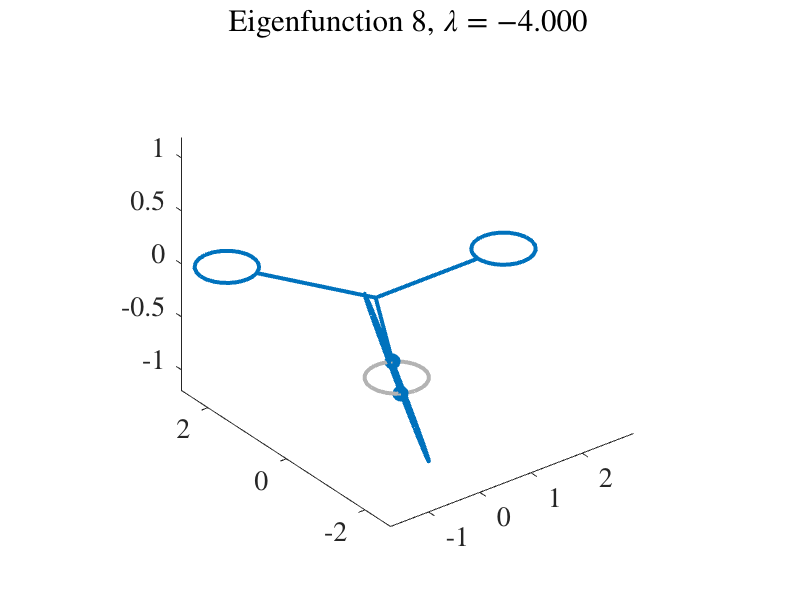

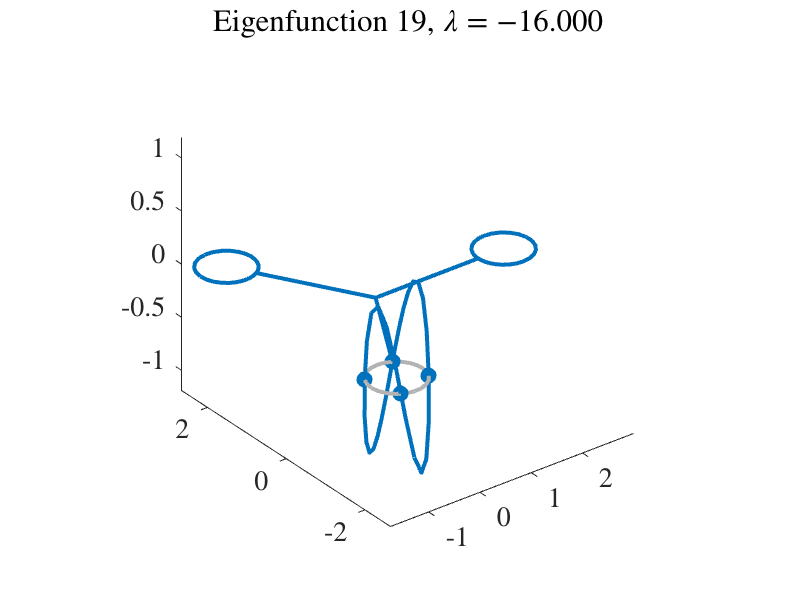

for k=1:min(nToPlot,length(triples))
    figure
    v=tribellResolveTriples(V,triples(k),Phi);
    Phi.plot(v{1})
    title(sprintf('Eigenfunction %i, $\\lambda = %0.3f$',triples(k), lambda(triples(k))));
end